# Deploy controller logic onto TI microcontroller

For this example, we are going to use TI Microcontroller Developement Kit (see image below) as a production controller 

- We will deploy our [controller logic](matlab:open_system('focVelocityEncoder_F28069_RealTimeHarness');) for PMSM onto TI microcontroller using Embedded Coder.  

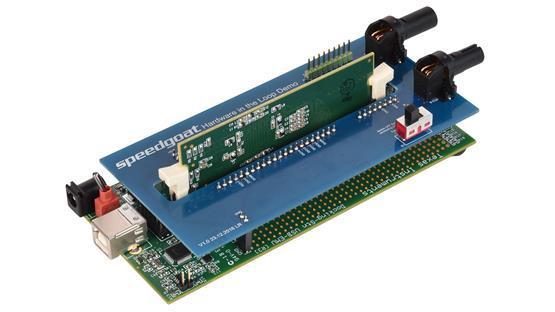

## Install and setup support package for C2000

From*** Add-On Explorer***, download and setup ***Embedded Coder Support Package for Texas Instruments C2000 Processors*** 

Learn more under: [https://mathworks.com/hardware-support/ti-c2000.html](https://mathworks.com/hardware-support/ti-c2000.html)

Make sure that you have installed all required third party software. Click on the "Set up" button in AddOn Manager in order to explore the status of third party software setup. 

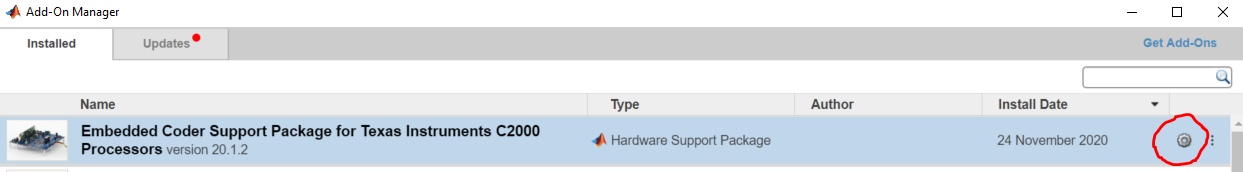

## **Deploy Controller Model on TI F2806x ISO controlCARD**

`NOTE:` `Ensure TI controlCard is connected to Host-Machine via USB Cable`

Check COM port of USB device XDS100 in Device Manager:

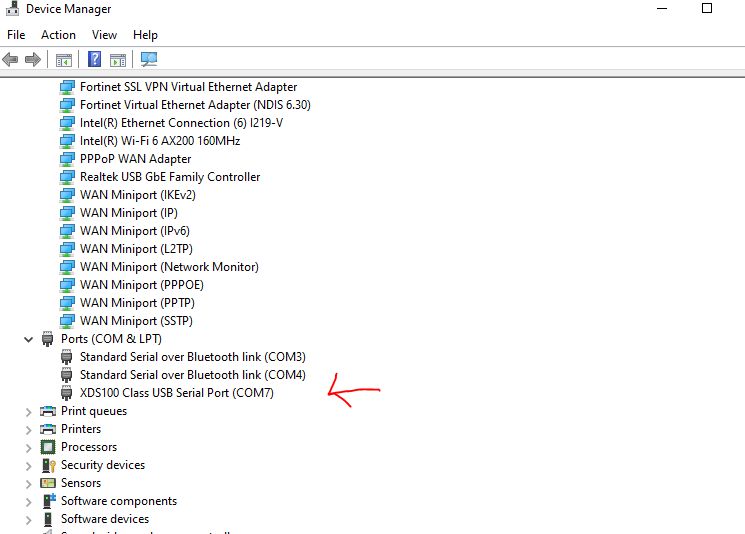

## Explore protected model using Motor Control Blockset

`The controller referenced by the deployment model uses Mathworks's Motor Control Blockset toolbox. A protected model was generated to allow user to view, run and generate code from a top model referencing this controller, without the toolbox. Explore this model web view:`

Simulink.ProtectedModel.open('focVelocityEncoder','webview')

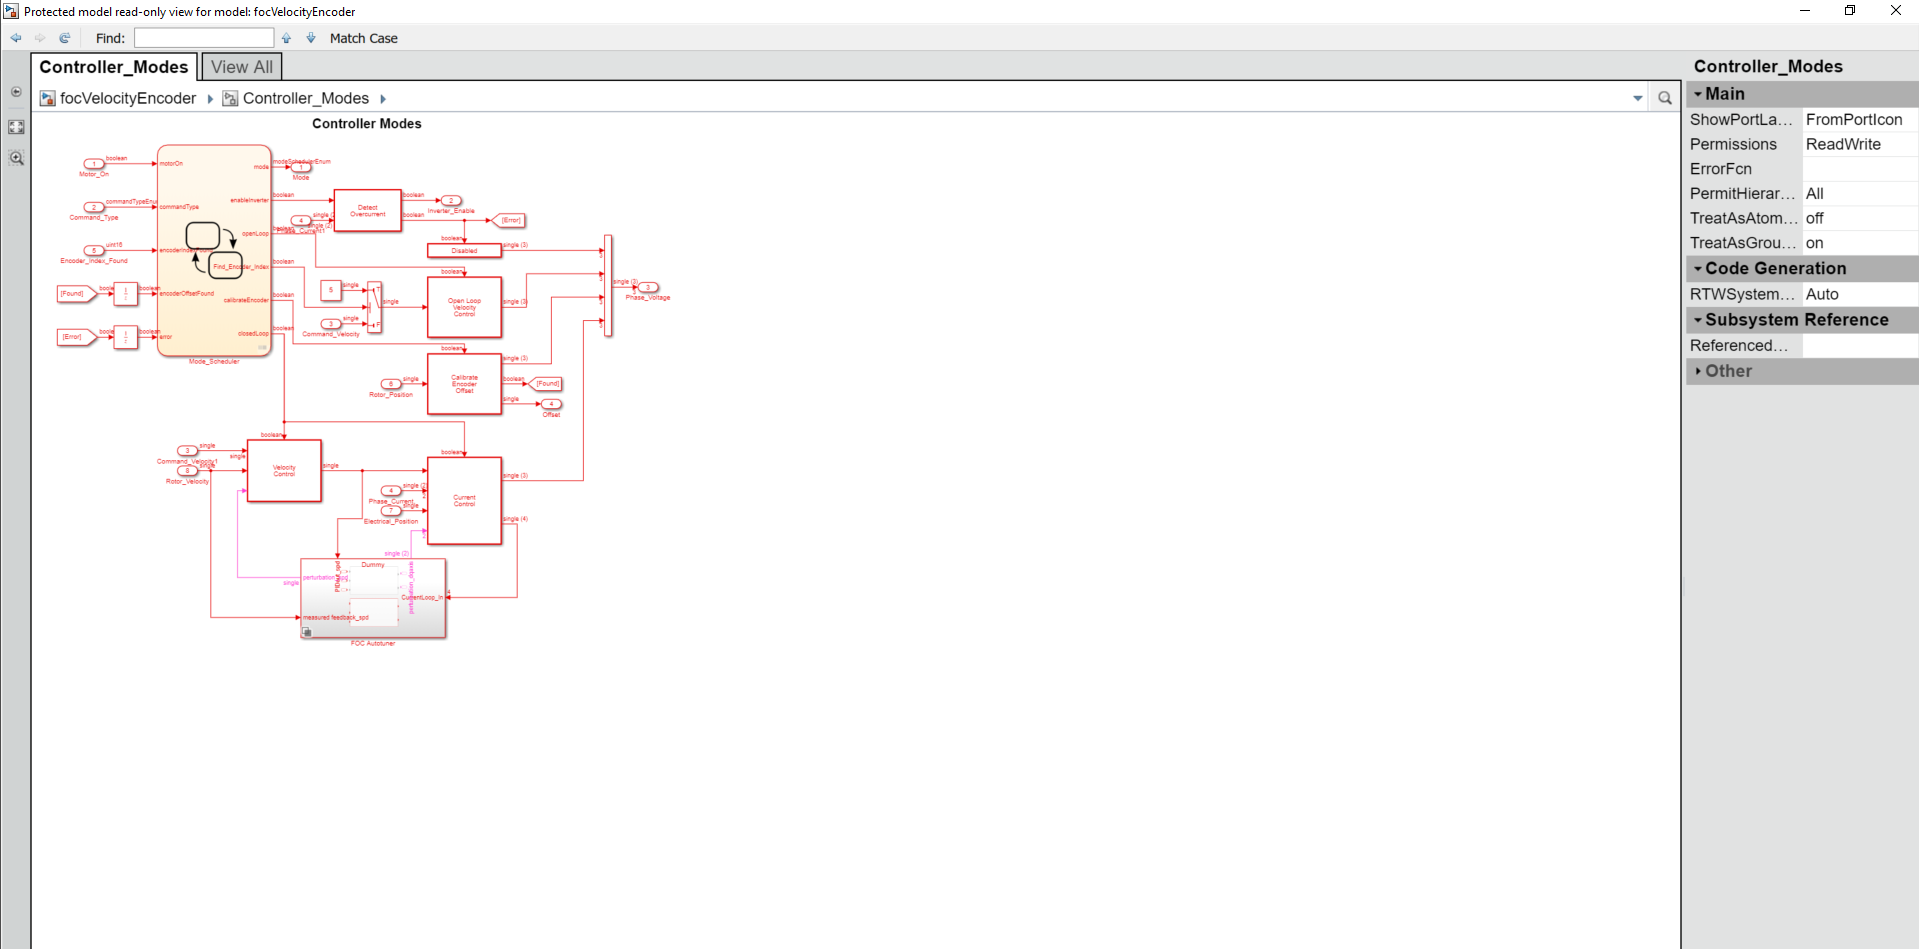

If your MATLAB setup contains the Motor Control Blockset toolbox you can open and edit the original model 

open_system('focVelocityEncoder')

## Deploy model to embedded target

mdl = 'focVelocityEncoder_F28069';
open_system(mdl);
%switchMotorKit('SG_Inverter_RCP_Kit');
%switchConfig('EC');
% Change Controller Model Calibration for TI Board
%ddCntrl = Simulink.data.dictionary.open('SGKitControllerData.sldd');
%setValue(getEntry(ddCntrl.getSection('Design Data'),'paramAdcAmperePerTransducerVolt'),[15.0150, 15.0150]);
%etValue(getEntry(ddCntrl.getSection('Design Data'),'paramAdcTransducerVoltAtZeroAmpere'),1.65);
% Build and Deploy Code to TI Controller
rtwbuild(mdl);

### Starting serial model reference code generation build
### Checking the status of model reference code generation target for model 'focVelocityEncoder' used in 'focVelocityEncoder_F28069'


### Model reference code generation target (focVelocityEncoder.c) for model focVelocityEncoder must be recompiled because either focVelocityEncoder.c has changed since the last build, or it has never been compiled.
### Starting build procedure for: focVelocityEncoder
### Generating code and artifacts to 'Model specific' folder structure


### Code for the model reference code generation target for model focVelocityEncoder is up to date because no functional changes were found in the referenced model.


### Evaluating PostCodeGenCommand specified in the model
### Using toolchain: Texas Instruments Code Composer Studio (C2000)
### Creating 'C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\focVelocityEncoder\focVelocityEncoder.mk' ...
### Building 'focVelocityEncoder_rtwlib': "C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f focVelocityEncoder.mk all

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\focVelocityEncoder>cd . 

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\focVelocityEncoder>chcp 1252 
Active code page: 1252

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\focVelocityEncoder>if "" == "" ("C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f focVelocityEncoder.mk all )  else ("C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f focVelocityEncoder.mk  ) 
"C:/PROGRA~3/MATLAB/SUPPOR~1/R2020a/3P778C~1.INS/TIC200~1.INS/TI-CGT~1.LTS/bin/cl2000" -

### Generated code for 'focVelocityEncoder_F28069' is up to date because no structural, parameter or code replacement library changes were found.


### Evaluating PostCodeGenCommand specified in the model
### Using toolchain: Texas Instruments Code Composer Studio (C2000)
### 'C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\_sharedutils\rtwshared.mk' is up to date
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f rtwshared.mk all

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\_sharedutils>cd . 

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\_sharedutils>chcp 1252 
Active code page: 1252

C:\Workspace\GitHub\Electric-Motor-Control\P-Electric-Motor-Control\Work\slprj\ert\_sharedutils>if "" == "" ("C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f rtwshared.mk all )  else ("C:\PROGRA~1\MATLAB\R2020a\bin\win64\gmake"  -B -f rtwshared.mk  ) 
"C:/PROGRA~3/MATLAB/SUPPOR~1/R2020a/3P778C~1.INS/TIC200~1.INS/TI-CGT~1.LTS/bin/cl2000" --compile_only --large_memory_model --silicon_version=28 --define="LARGE_MOD